# Walking Robot: Inverse Kinematics with Symbolic Math Toolbox

#### Define and solve symbolic equations

% syms x y L1 L2 theta1 theta2 real
syms L1 L2 L3 L4 h1 l1 l2 l3 l4 m1 m2 m3 m4 real positive
syms COM_x COM_y theta1 theta2 theta3 theta4 x1 x2 x3 x4 y1 y2 y3 y4 real
t1 = theta1;
t11 = t1 + pi/2;
t2 = t11 + theta2;
t3 = t2 + theta3;
t4 = t3 + theta4;

## Sit-to-stand case

Find all geometric angles

warning off
% solve theta1
theta1eqx = x1 == L1*cos(t1);
theta1eqy = y1 == L1*sin(t1);
sol1 = solve(theta1eqy, ...
    theta1, 'Real', true);
t1sol = simplify(sol1(1), ...
    "All",true,"Criterion","preferReal","IgnoreAnalyticConstraints",true);

% solve theta2
theta2eqx = x2 == rhs(theta1eqx) + h1*cos(t11) + L2*cos(t2);
theta2eqy = y2 == rhs(theta1eqy) + h1*sin(t11) + L2*sin(t2);
sol2 = solve(subs(theta2eqy, t1, t1sol), ...
    theta2, 'Real', true);
t2sol = simplify(sol2(1), ...
    "Criterion","preferReal","IgnoreAnalyticConstraints",true);

% solve theta3
theta3eqx = x3 == rhs(theta2eqx) + L3*cos(t3);
theta3eqy = y3 == rhs(theta2eqy) + L3*sin(t3);
sol3 = solve(subs(theta3eqy, [theta1 theta2], [t1sol t2sol]), ...
    theta3, 'Real', true);
t3sol = simplify(sol3(1), ...
    "Criterion","preferReal","IgnoreAnalyticConstraints",true);

% solve theta4
theta4eqx = x4 == rhs(theta3eqx) + L4*cos(t4);
theta4eqy = y4 == rhs(theta3eqy) + L4*sin(t4);
sol4 = solve(subs(theta4eqy, [theta1 theta2 theta3], [t1sol t2sol t3sol]), ...
    theta4, 'Real', true);
t4sol = simplify(sol4(1), ...
    "Criterion","preferReal","IgnoreAnalyticConstraints",true);

x1m = simplify(subs(rhs(theta1eqx), L1, l1));
y1m = simplify(subs(rhs(theta1eqy), L1, l1));
x2m = simplify(subs(rhs(theta2eqx), L2, l2));
y2m = simplify(subs(rhs(theta2eqy), L2, l2));
x3m = simplify(subs(rhs(theta3eqx), L3, l3));
y3m = simplify(subs(rhs(theta3eqy), L3, l3));
x4m = simplify(subs(rhs(theta4eqx), L4, l4));
y4m = simplify(subs(rhs(theta4eqy), L4, l4));

Mtotal = m1 + m2 + m3 + m4;

COMxeq = simplify(1/Mtotal*(m1*x1m + m2*x2m + m3*x3m + m4*x4m), ...
    "Criterion","preferReal","IgnoreAnalyticConstraints",true,"Steps",50);
COMyeq = simplify(1/Mtotal*(m1*y1m + m2*y2m + m3*y3m + m4*y4m), ...
    "Criterion","preferReal","IgnoreAnalyticConstraints",true,"Steps",50);

% sol2 = solve(theta)
% sol2 = solve(theta2eqy, theta2);
warning on

clf, close all
subsVars = {L1 L2 L3 L4 h1 ...
    x1 x2 x3 x4 ...
    y1 y2 y3 y4 ...
    m1 m2 m3 m4 ...
    l1 l2 l3 l4};
subsValues = {50 400 400 500 30 ...
    10 50 150 20 ...
    0 400 600 1100 ...
    1 5 6 20 ...
    25 200 200 250};

% plot([0 20 50 150], [0 30 350 850], 'bo-'), axis equal, grid on

theta1n = double(subs(t1sol, subsVars, subsValues));
theta2n = double(subs(t2sol, subsVars, subsValues));
theta3n = double(subs(t3sol, subsVars, subsValues));
theta4n = double(subs(t4sol, subsVars, subsValues));
thetas = [theta1n theta2n theta3n theta4n]

thetas =          0   -0.3898   -0.6574    1.0472


rad2deg([theta1n theta2n theta3n theta4n])

ans =          0  -22.3316  -37.6684   60.0000


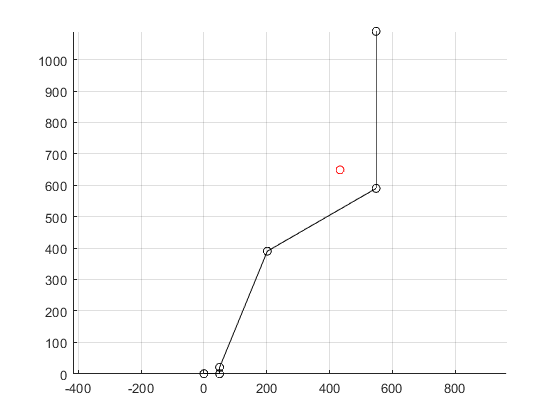

subsVars2 = {L1 L2 L3 L4 h1 ...
    l1 l2 l3 l4 ...
    m1 m2 m3 m4 ...
    theta1 theta2 theta3 theta4};
% subsValues2 = {50 400 400 500 20 ...
%     25 200 200 250 ...
%     1 5 6 20 ...
%     theta1n theta2n theta3n theta4n};
subsValues2 = {50 400 400 500 20 ...
    25 200 200 250 ...
    1 5 6 20 ...
    theta1n theta2n theta3n theta4n};
%     0.0007 6.2809 6.0651 2.1351}; 
hold on
plot([0 ...
    double(subs(rhs(theta1eqx), subsVars2, subsValues2)) ...
    double(subs(rhs(theta1eqx) + h1*cos(t11), subsVars2, subsValues2)) ...
    double(subs(rhs(theta2eqx), subsVars2, subsValues2)) ...
    double(subs(rhs(theta3eqx), subsVars2, subsValues2)) ...
    double(subs(rhs(theta4eqx), subsVars2, subsValues2))], ...
    [0 ...
    double(subs(rhs(theta1eqy), subsVars2, subsValues2)) ...
    double(subs(rhs(theta1eqy) + h1*sin(t11), subsVars2, subsValues2)) ...
    double(subs(rhs(theta2eqy), subsVars2, subsValues2)) ...
    double(subs(rhs(theta3eqy), subsVars2, subsValues2)) ...
    double(subs(rhs(theta4eqy), subsVars2, subsValues2))], 'ko-')
plot(double(subs(COMxeq, subsVars2, subsValues2)), ...
    double(subs(COMyeq, subsVars2, subsValues2)), 'ro')
axis equal, grid on, hold off

### Test

% thetasn = matlabFunction([t1sol t2sol t3sol t4sol],'File','Tests\legInvKin');
% COM = matlabFunction([COMxeq COMyeq],'File','Tests\COMTrajectory');
% clear
double(subs(COMxeq, subsVars2, subsValues2))

ans = 433.5643

double(subs(COMyeq, subsVars2, subsValues2))

ans = 648.9063

#### Evaluate the solution for a given set of values

% % subsVars = {L1, L2, x, y};
% % subsValues = {0.1, 0.12, 0.05, -0.15};
% % 
% COMTrajectory(50,400,400,30,25,200,200,250,1,5,6,20,rand(20,1),rand(20,1),rand(20,1),rand(20,1))

% theta1val = double(subs(soln.theta1,subsVars,subsValues))
% theta2val = double(subs(soln.theta2,subsVars,subsValues))

#### Save solution to a MATLAB Function

% matlabFunction([soln.theta1,soln.theta2],'File','legInvKin');

Notice that there can be two solutions for the same position. We can process this by choosing an answer that makes physical sense -- for example, the knee is not allowed to bend backwards.

Idea: path generation with initial and ending boundary. The body moves such that the least amount of energy (kinetic + potential energy) is used:

posture_beginning = [0 0 -pi/2 pi/2];
posture_ending = [0 0 0 0];